# *IDENTIFICACION DEL SISTEMA*

## *PROCESS MODELS*

*D:\TRABAJO\UMAKER\TALLERES\CONTROL PID - MOTOR DC\CODIGO\Keil_DATA_ADQUISITION*

clear all,close all,clc
%Cargar data
load('y.dat')
load('u.dat')
Ts=4e-3;                   %PERIODO DE MUESTREO 4ms

OBTENER INFORMACIÓN DE LAS PRIMERAS M muestras

TIEMPO DE INTERES

tM=1;
M=round(tM/Ts);
y1=y(1:M);                 %se obtiene solo la cantidad de dato necesaria
y1=filter(ones(1,4),1,y1)*1/4;  %se aplica un diesmado

SEÑAL DE CONTROL ESCALÓN (PRUEBAS HECHAS)

ut=u(1:M,1);

## RESPUESTA DEL SISTEMA

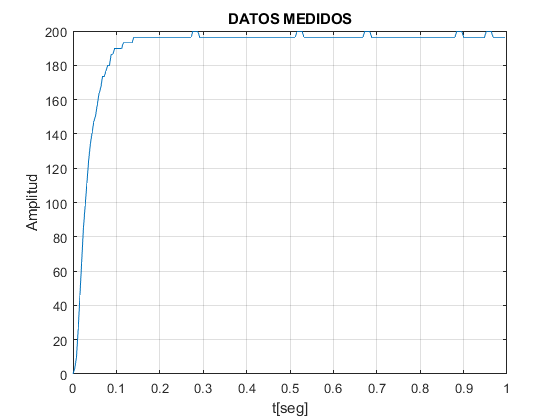

yt=y1;
%VECTOR TIEMPO DISCRETO
n=0:M-1;
%VECTOR TIEMPO CONTINUO
t=n*Ts;
%---STEP
figure("Name","datos muestreados")
plot(t,y1)
grid on
title('DATOS MEDIDOS')
xlabel('t[seg]')
ylabel('Amplitud')

### ESTIMACION DEL PROCESO

data = iddata(yt,ut,Ts);
np=2;                   %Número de polos
nz=0;                   %Número de zeros

FUNCIÓN DE TRANSFERENCIA DEL MOTOR DC 

TF1= tfest(data,np,nz)

TF1 =
 
  From input "u1" to output "y1":
        1.499e05
  --------------------
  s^2 + 216.1 s + 6373
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 96.18%                   
FPE: 1.326, MSE: 1.274                           


b=TF1.Numerator;
a=TF1.Denominator;
figure("Name","RESPUESTA DEL SISTEMA A UNA ENTRADA ESCALON")
yb=1*step(TF1,t);
Gp=tf(b,a)

Gp =
 
        1.499e05
  --------------------
  s^2 + 216.1 s + 6373
 
Continuous-time transfer function.



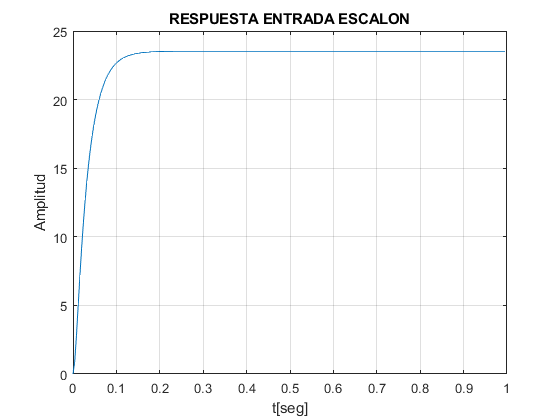

figure("Name","respuesta escalon del sistema")
plot(t,yb)
title('RESPUESTA ENTRADA ESCALON')
xlabel('t[seg]')
ylabel('Amplitud')
grid on

obtener el periodo de muestreo

%método del diagrama de bode
[aux wgc]=margin(Gp);
%Periodo de muestreo minimo en terminos
%del margen de ganancia del diagrama de bode
Tss_min=1/(20*wgc)

Tss_min = 0.0016

## **VALIDACION DEL MODELO**

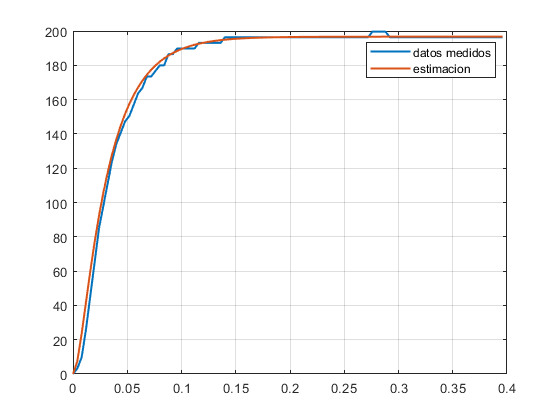

N = 100;                %solo las primeras 100 muestras
t = (0:Ts:(N-1)*Ts)';
yk = lsim(Gp,ut(1:100,1),t);
figure("Name","Validacion del modelo")
plot(t,yt(1:N,1),'LineWidth',1.5,'LineStyle',"-")
hold on
plot(t,yk,'LineWidth',1.5)
grid on
legend('datos medidos','estimacion')